# **Does phenotype explain the variance in regional fibre counts?**

This analysis builds linear mixed effects models (LMEM) that evaluate the influence of phenotype on regional fibre count, to establish whether one or many phenotypes influence fibre counts in key regions across the brain. 

Step 1: Set up the data

% Load the table with your data 
TABLE=readtable('TH Overall Total_Coding.xlsx');

% Write the headers for your table here
names={'Cases','LCTH','HippTH','FCTH','CCTH','AmyTH','ThalTH','Total','Phenotype','_1' ,'_2','_3','_4','_5','_6','_7'};
TABLE.Properties.VariableNames=names

TABLE = 80×16 table
      Cases      LCTH    HippTH    FCTH    CCTH    AmyTH    ThalTH    Total    Phenotype         _1        _2     _3     _4     _5         _6            _7    
    _________    ____    ______    ____    ____    _____    ______    _____    __________    __________    ___    ___    ___    ___    __________    __________

    {'PD343'}      7        4       58      20      NaN      106       195     {'DLB'   }    {0×0 char}    NaN    N


% Add the paths for the functions we need
addpath('C:\Users\dk00549\OneDrive - University of Surrey\Documents\Surrey\MATLAB\PluginsProgramsToolboxes\gramm-master')
addpath('C:\Users\dk00549\OneDrive - University of Surrey\Documents\Surrey\MATLAB\PluginsProgramsToolboxes\violinplot')

Step 2: Computing LMEM assessing whether Phenotype influences the variance within the seven predicted values. We include subjects as random effects to help explain interindividual variability in the model. 

LCTH_Model = fitglme(TABLE,'LCTH ~ Phenotype + (1|Cases)','Distribution',"Normal"); 
disp(LCTH_Model)

Generalized linear mixed-effects model fit by PL

Model information:
    Number of observations              80
    Fixed effects coefficients           5
    Random effects coefficients         80
    Covariance parameters                2
    Distribution                    Normal
    Link                            Identity
    FitMethod                       MPL   

Formula:
    LCTH ~ 1 + Phenotype + (1 | Cases)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    676.96    693.63    -331.48          662.96  

Fixed effects coefficients (95% CIs):
    Name                         Estimate    SE        tStat      DF    pValue        Lower      Upper 
    {'(Intercept)'      }         8.3333     5.0832     1.6394    75       0.10532    -1.7929     18.46
    {'Phenotype_PD'     }         8.2778     6.2256     1.3296    75       0.18767    -4.1242     20.68
    {'Phenotype_PDD'


HippTH_Model = fitglme(TABLE,'HippTH ~ Phenotype + (1|Cases)','Distribution',"Normal"); 
disp(HippTH_Model)

Generalized linear mixed-effects model fit by PL

Model information:
    Number of observations              76
    Fixed effects coefficients           5
    Random effects coefficients         76
    Covariance parameters                2
    Distribution                    Normal
    Link                            Identity
    FitMethod                       MPL   

Formula:
    HippTH ~ 1 + Phenotype + (1 | Cases)

Model fit statistics:
    AIC       BIC      LogLikelihood    Deviance
    794.09    810.4    -390.04          780.09  

Fixed effects coefficients (95% CIs):
    Name                         Estimate    SE        tStat       DF    pValue      Lower      Upper 
    {'(Intercept)'      }         7.1111     13.662     0.52051    71     0.60433     -20.13    34.352
    {'Phenotype_PD'     }         18.948     16.896      1.1215    71     0.26587    -14.741    52.636
    {'Phenotype_PDD'   


FCTH_Model = fitglme(TABLE,'FCTH ~ Phenotype + (1|Cases)','Distribution',"Normal"); 
disp(FCTH_Model)

Generalized linear mixed-effects model fit by PL

Model information:
    Number of observations              53
    Fixed effects coefficients           5
    Random effects coefficients         53
    Covariance parameters                2
    Distribution                    Normal
    Link                            Identity
    FitMethod                       MPL   

Formula:
    FCTH ~ 1 + Phenotype + (1 | Cases)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    722.68    736.48    -354.34          708.68  

Fixed effects coefficients (95% CIs):
    Name                         Estimate    SE        tStat         DF    pValue     Lower      Upper 
    {'(Intercept)'      }          151.25    96.894         1.561    48     0.1251    -43.568    346.07
    {'Phenotype_PD'     }          107.68    109.05       0.98747    48    0.32837    -111.58    326.94
    {'Phenotype_PDD'


CCTH_Model = fitglme(TABLE,'CCTH ~ Phenotype + (1|Cases)','Distribution',"Normal"); 
disp(CCTH_Model)

Generalized linear mixed-effects model fit by PL

Model information:
    Number of observations              78
    Fixed effects coefficients           5
    Random effects coefficients         78
    Covariance parameters                2
    Distribution                    Normal
    Link                            Identity
    FitMethod                       MPL   

Formula:
    CCTH ~ 1 + Phenotype + (1 | Cases)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    916.22    932.71    -451.11          902.22  

Fixed effects coefficients (95% CIs):
    Name                         Estimate    SE        tStat      DF    pValue      Lower      Upper 
    {'(Intercept)'      }        30.111      26.203     1.1491    73     0.25425    -22.112    82.334
    {'Phenotype_PD'     }        80.611      32.092     2.5119    73    0.014221     16.651    144.57
    {'Phenotype_PDD'    } 


AmyTH_Model = fitglme(TABLE,'AmyTH ~ Phenotype + (1|Cases)','Distribution',"Normal"); 
disp(AmyTH_Model)

Generalized linear mixed-effects model fit by PL

Model information:
    Number of observations              50
    Fixed effects coefficients           5
    Random effects coefficients         50
    Covariance parameters                2
    Distribution                    Normal
    Link                            Identity
    FitMethod                       MPL   

Formula:
    AmyTH ~ 1 + Phenotype + (1 | Cases)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    639.88    653.27    -312.94          625.88  

Fixed effects coefficients (95% CIs):
    Name                         Estimate    SE        tStat      DF    pValue        Lower      Upper  
    {'(Intercept)'      }            359      73.01     4.9171    45    1.2116e-05     211.95     506.05
    {'Phenotype_PD'     }           -320     83.244    -3.8441    45    0.00037749    -487.66    -152.34
    {'Phenotype_


ThalTH_Model = fitglme(TABLE,'ThalTH ~ Phenotype + (1|Cases)','Distribution',"Normal"); 
disp(ThalTH_Model)

Generalized linear mixed-effects model fit by PL

Model information:
    Number of observations              73
    Fixed effects coefficients           5
    Random effects coefficients         73
    Covariance parameters                2
    Distribution                    Normal
    Link                            Identity
    FitMethod                       MPL   

Formula:
    ThalTH ~ 1 + Phenotype + (1 | Cases)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    893.51    909.54    -439.75          879.51  

Fixed effects coefficients (95% CIs):
    Name                         Estimate    SE        tStat       DF    pValue      Lower      Upper 
    {'(Intercept)'      }             40      33.33      1.2001    68     0.23426     -26.51    106.51
    {'Phenotype_PD'     }         94.294     41.219      2.2876    68    0.025276     12.042    176.55
    {'Phenotype_PDD' 


Total_Model = fitglme(TABLE,'Total ~ Phenotype + (1|Cases)','Distribution',"Normal"); 
disp(Total_Model)

Generalized linear mixed-effects model fit by PL

Model information:
    Number of observations              80
    Fixed effects coefficients           5
    Random effects coefficients         80
    Covariance parameters                2
    Distribution                    Normal
    Link                            Identity
    FitMethod                       MPL   

Formula:
    Total ~ 1 + Phenotype + (1 | Cases)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    1146.2    1162.9    -566.12          1132.2  

Fixed effects coefficients (95% CIs):
    Name                         Estimate    SE        tStat       DF    pValue       Lower      Upper 
    {'(Intercept)'      }         272.44     95.484      2.8533    75    0.0055896      82.23    462.66
    {'Phenotype_PD'     }         243.78     116.94      2.0846    75     0.040513     10.814    476.74
    {'Phenotype_PDD

Note that including subjects as random effects explains *all *of the remaining variance left in the models. I've never seen that, and I'm not quite sure it's a good thing - I'm concerned our models are overfitting, and because we have so few datapoints, this is likely the case. Since we're not going to impute or gather more data, we can work with what we have while considering the effect our low sample size may have on model performance. 

Step 3: Because we've run seven models, each with the same predictor, we need to correct for seven multiple comparisons. We'll use FDR correction for multiple comparisons as our method. 

% This creates two tables - one to store our current p-vals in, the other,
% the FDR-corrected p-vals. 
Sig_Effects=[];
Sig_Effects_FDR=[];

% Now rows = PD, PDD, PD-MCI, and Control, and columns = region.
SigEffects(:,1)=LCTH_Model.Coefficients(1:4,6);
SigEffects(:,2)=HippTH_Model.Coefficients(1:4,6);
SigEffects(:,3)=FCTH_Model.Coefficients(1:4,6);
SigEffects(:,4)=CCTH_Model.Coefficients(1:4,6);
SigEffects(:,5)=AmyTH_Model.Coefficients(1:4,6);
SigEffects(:,6)=ThalTH_Model.Coefficients(1:4,6);
SigEffects(:,7)=Total_Model.Coefficients(1:4,6);

disp('Reminder: predicted values (protein scores) 1-7 = LCTH, HippTH, FCTH, CCTH, AmyTH, ThalTH, and Total')

Reminder: predicted values (protein scores) 1-7 = LCTH, HippTH, FCTH, CCTH, AmyTH, ThalTH, and Total


disp('Reminder: Predictors (phenotypes) are PD, PDD, PD_MCI, and Control')

Reminder: Predictors (phenotypes) are PD, PDD, PD_MCI, and Control


for ii=1:7
    tmp= table2array(dataset2table(SigEffects(:,ii)));
    [~,~,SigEffects_FDR(:,ii)]=fdr(tmp);
    
    for jj=1:height(SigEffects_FDR)
        if SigEffects_FDR(jj,ii)<0.05
            disp(strcat('Phenotype/Predictor ',num2str(jj),' significantly explains the variance within predicted value (protein)', num2str(ii)))
        end
    end
end

Phenotype/Predictor1 significantly explains the variance within predicted value (protein)5
Phenotype/Predictor2 significantly explains the variance within predicted value (protein)5
Phenotype/Predictor3 significantly explains the variance within predicted value (protein)5
Phenotype/Predictor4 significantly explains the variance within predicted value (protein)5
Phenotype/Predictor1 significantly explains the variance within predicted value (protein)7


Ok! We can see there's a significant effect of a few of the predictors, phenotype, on our predicted values, protein count. In particular, all phenotypes significantly explain the variance between AmyTH, and Total explains the variance between PD. In other words, all phenotypes have relationships with AmyTH, making it a potentially useful biomarker. One interesting question is can AmyTH fibre count explain the variance in Phenotypes? Since we've narrowed down our regions to this one, we can run one model to check.  I'll do that in a future analysis; MATLAB makes it tricky to do when the predicted var is a string. 

Let's make some plots! Looking at them, one ket limitation in our analysis is that we've got a small amount of data, and the variance among such few points may be driving our effect. Let's take that into consideration in our write-up. 

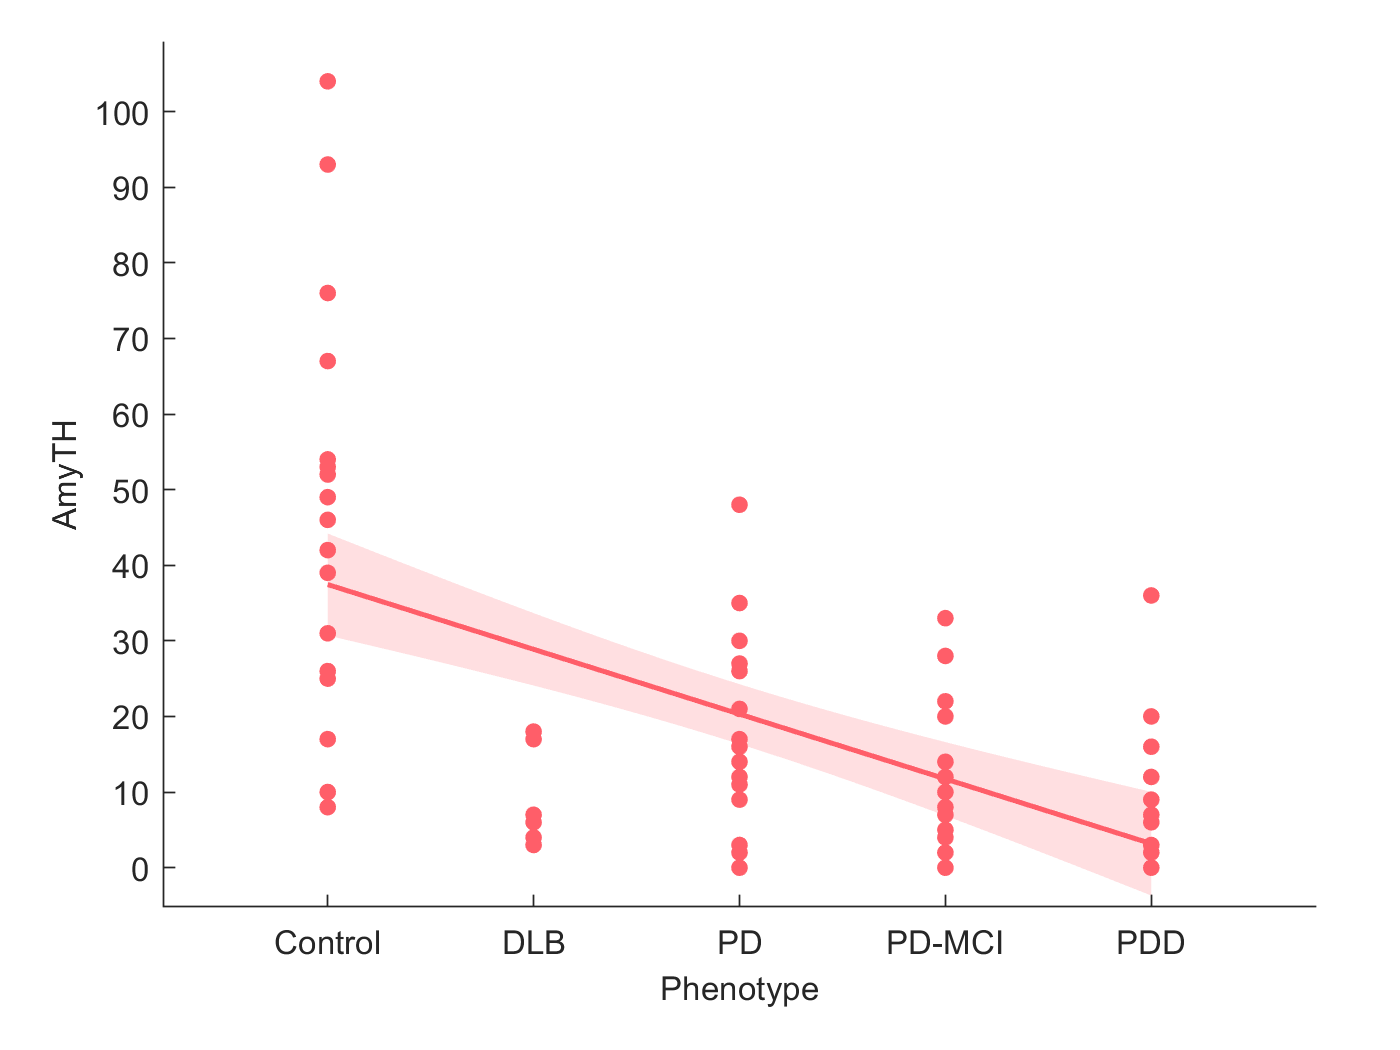

dt=gramm('x',TABLE.Phenotype,'y',TABLE.LCTH);
dt.geom_point();
dt.stat_glm();
dt.set_names('x','Phenotype','y','LCTH');
figure
dt.draw();

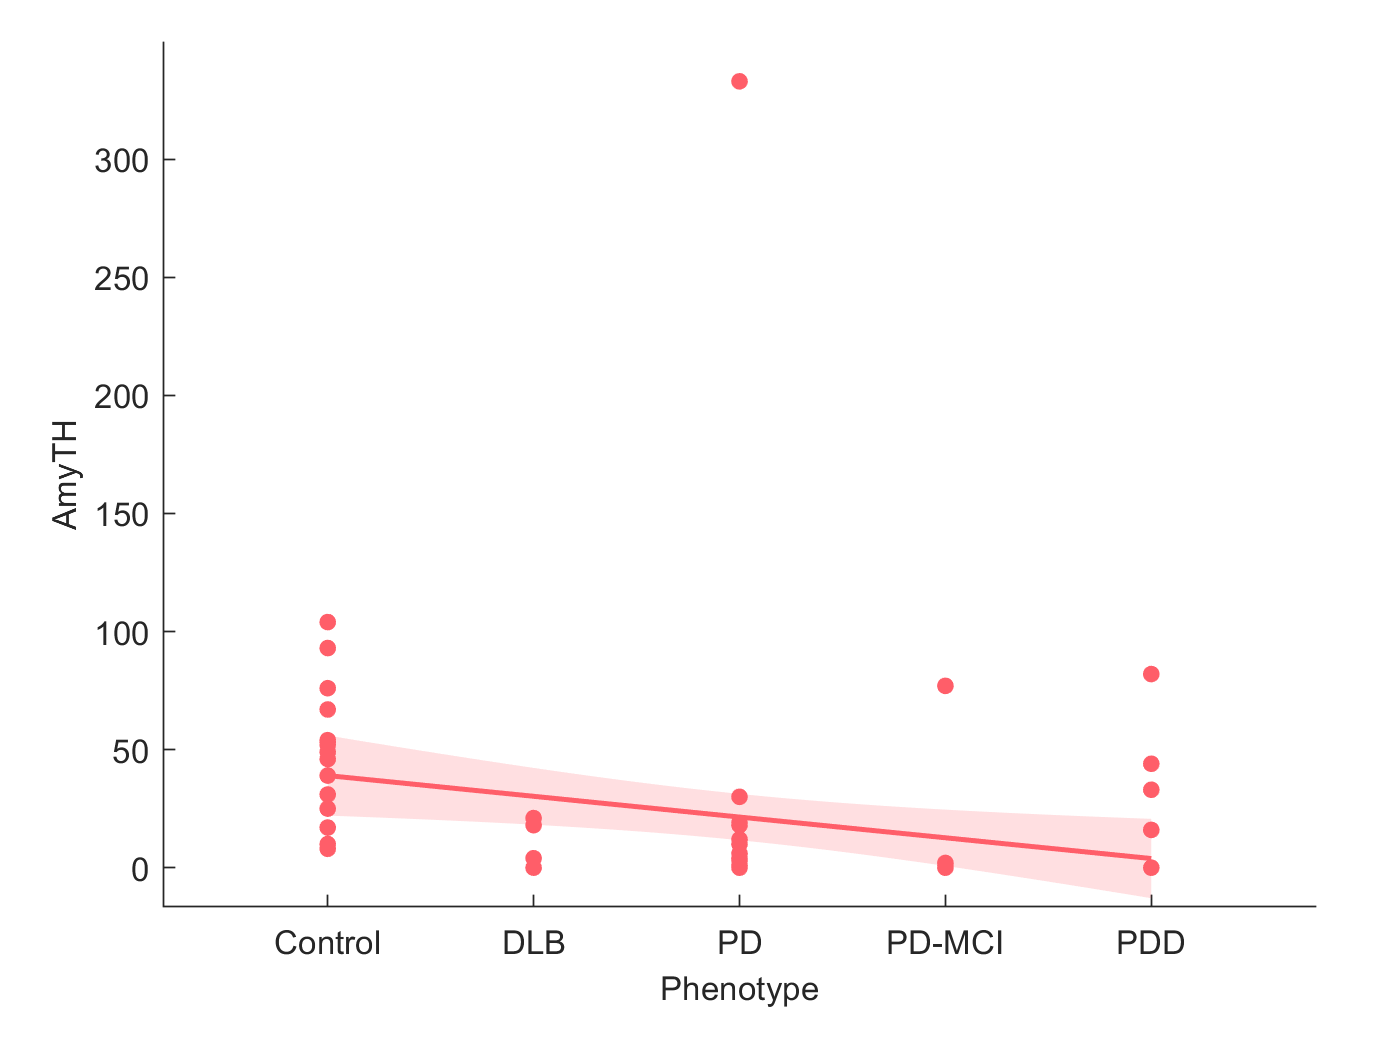


dt=gramm('x',TABLE.Phenotype,'y',TABLE.HippTH);
dt.geom_point();
dt.stat_glm();
dt.set_names('x','Phenotype','y','HippTH');
figure
dt.draw();

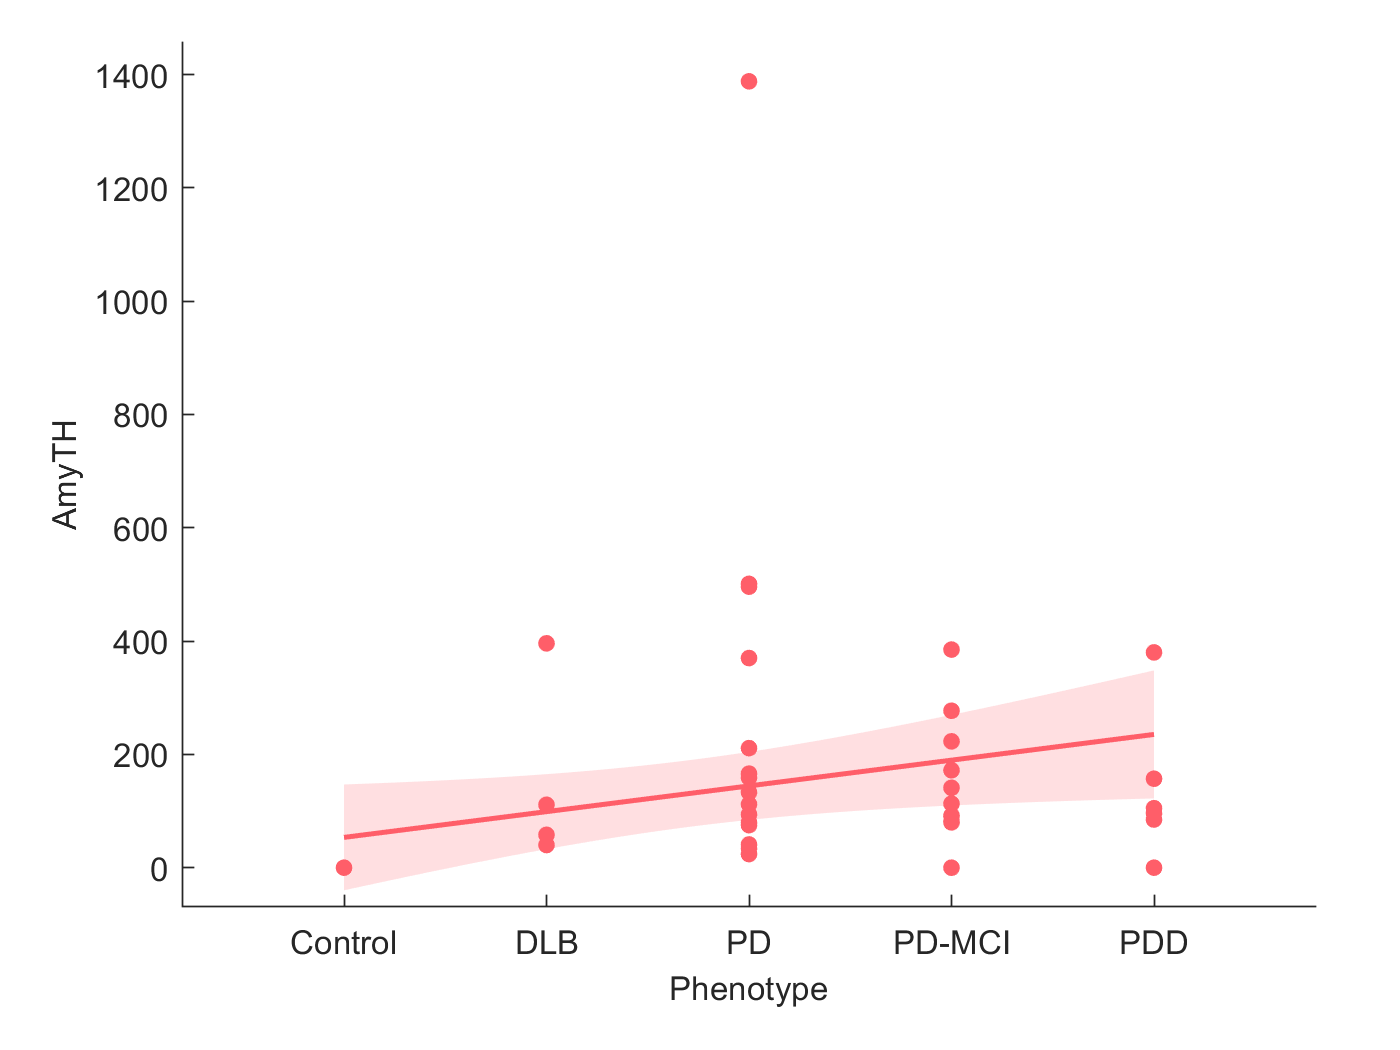


dt=gramm('x',TABLE.Phenotype,'y',TABLE.FCTH);
dt.geom_point();
dt.stat_glm();
dt.set_names('x','Phenotype','y','FCTH');
figure
dt.draw();

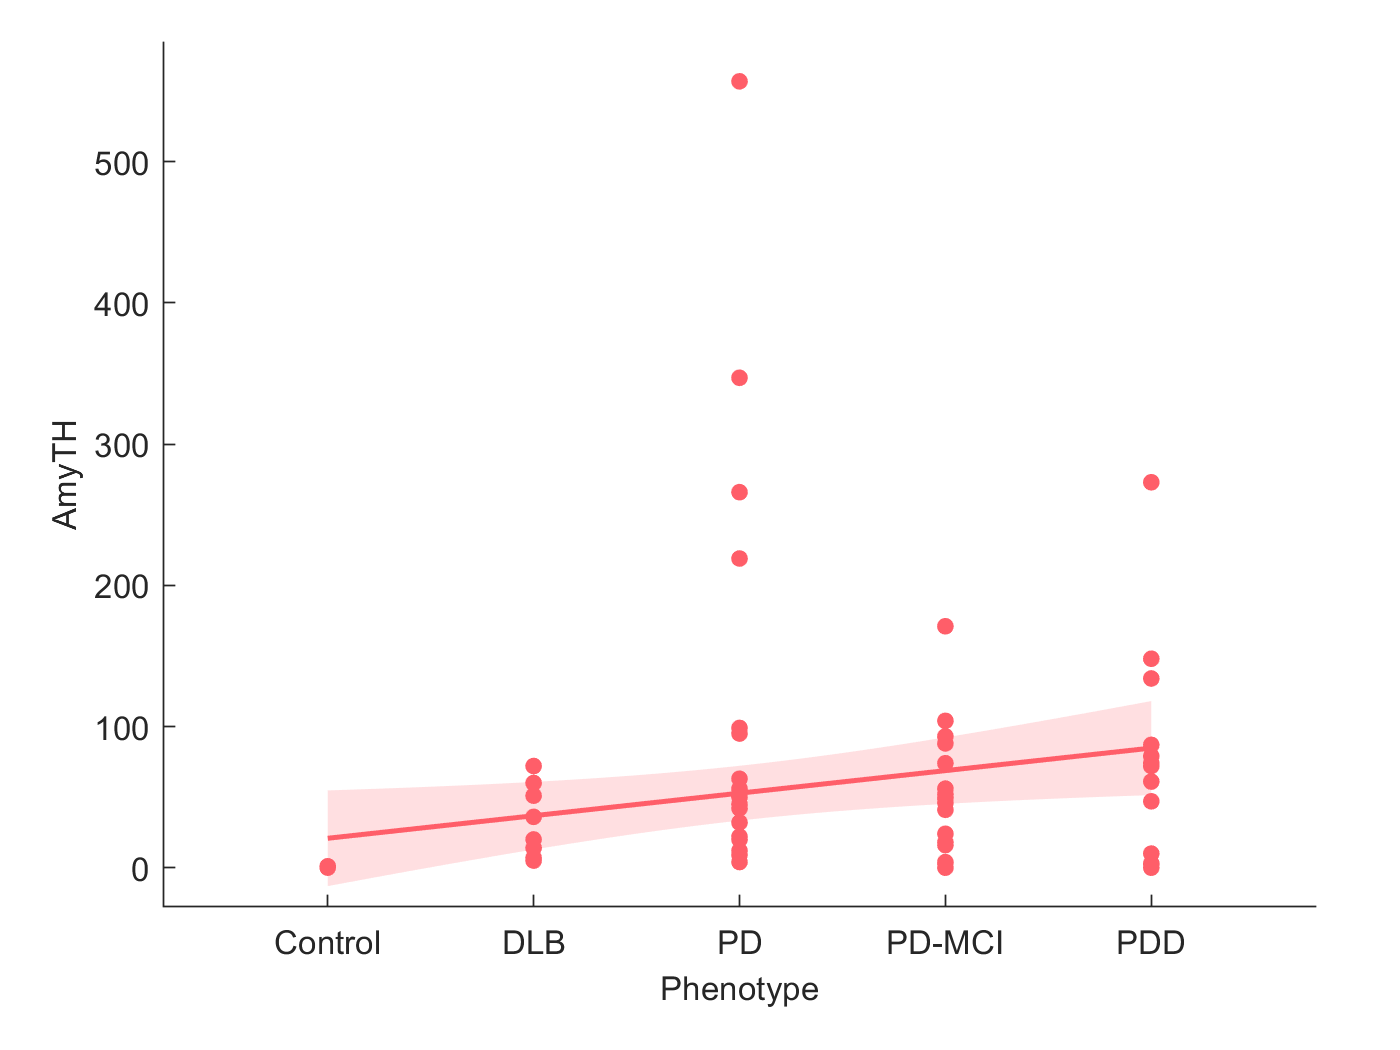


dt=gramm('x',TABLE.Phenotype,'y',TABLE.CCTH);
dt.geom_point();
dt.stat_glm();
dt.set_names('x','Phenotype','y','CCTH');
figure
dt.draw();

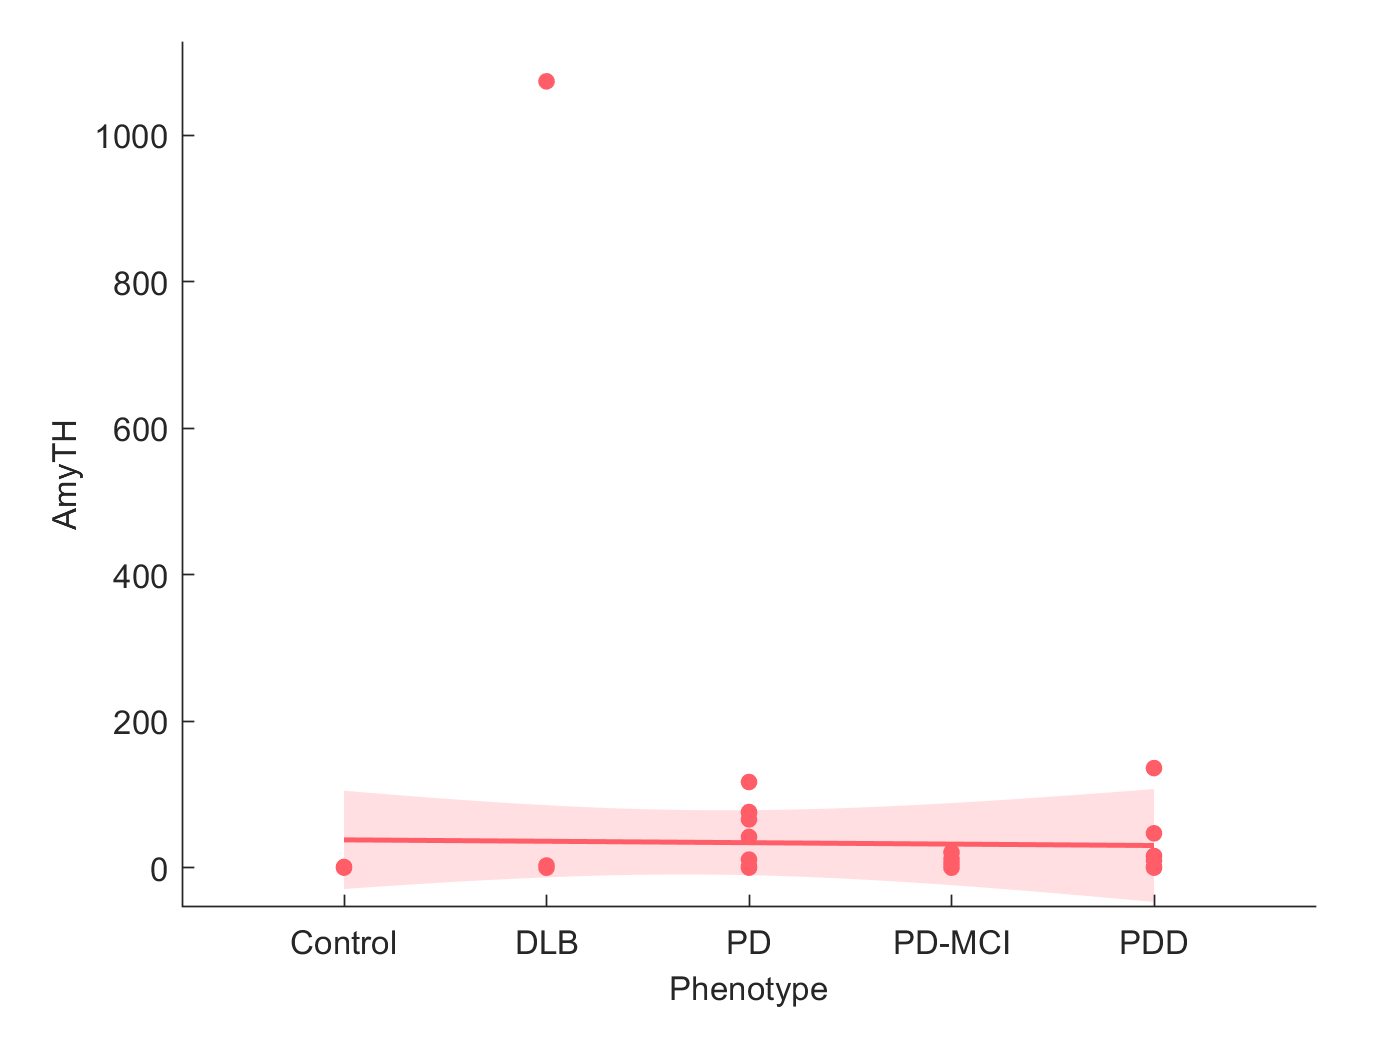


dt=gramm('x',TABLE.Phenotype,'y',TABLE.AmyTH);
dt.geom_point();
dt.stat_glm();
dt.set_names('x','Phenotype','y','AmyTH');
figure
dt.draw();

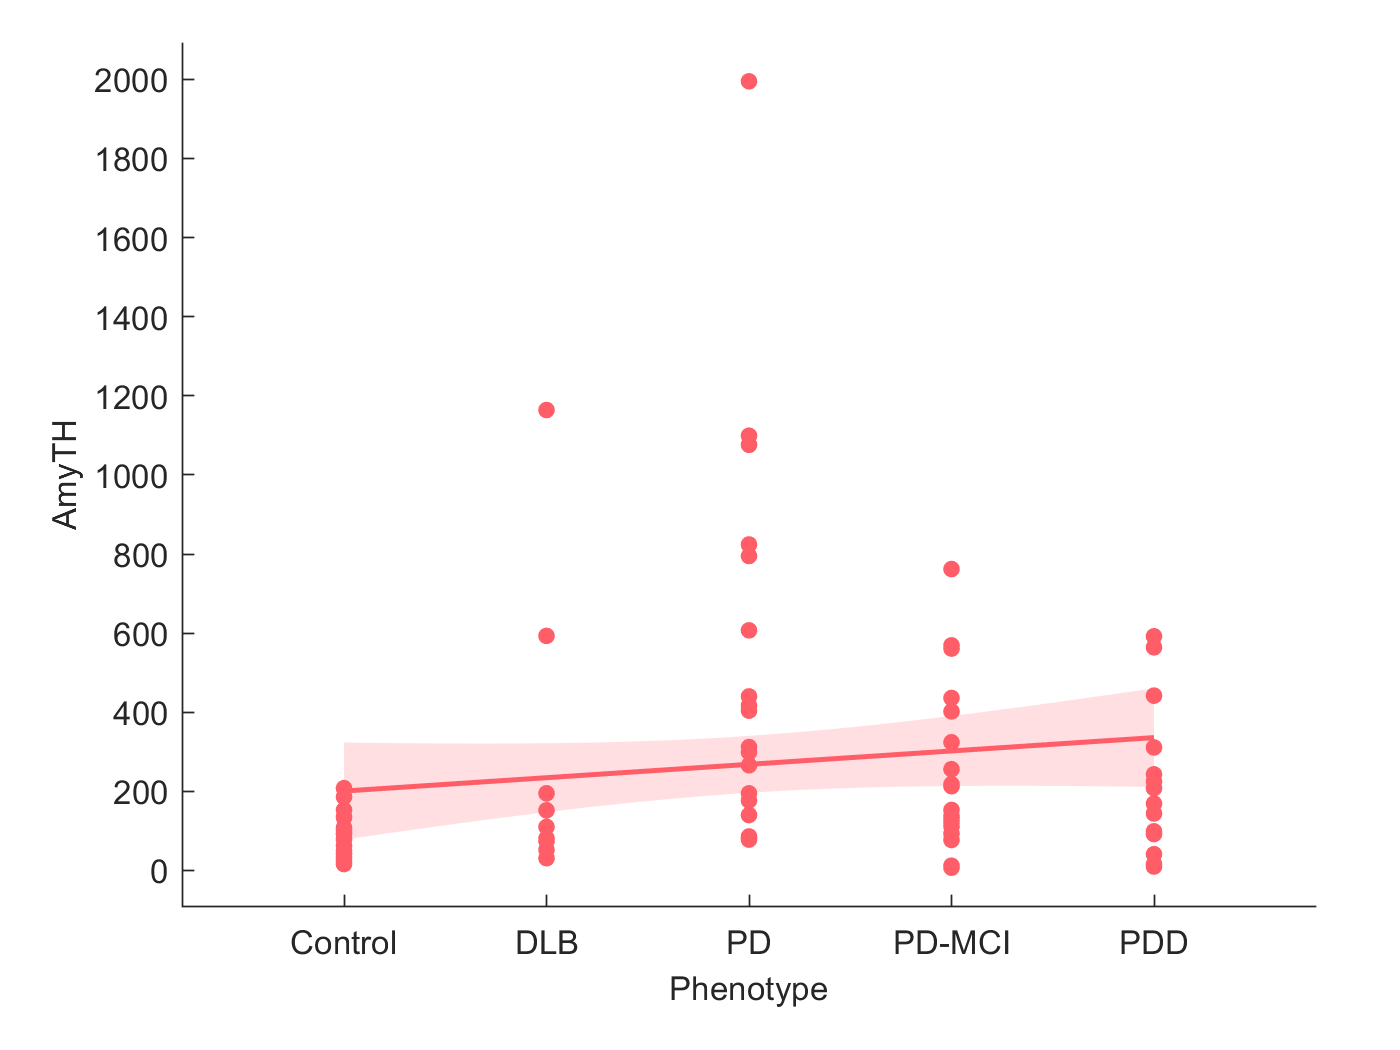


dt=gramm('x',TABLE.Phenotype,'y',TABLE.Total);
dt.geom_point();
dt.stat_glm();
dt.set_names('x','Phenotype','y','Total');
figure
dt.draw();

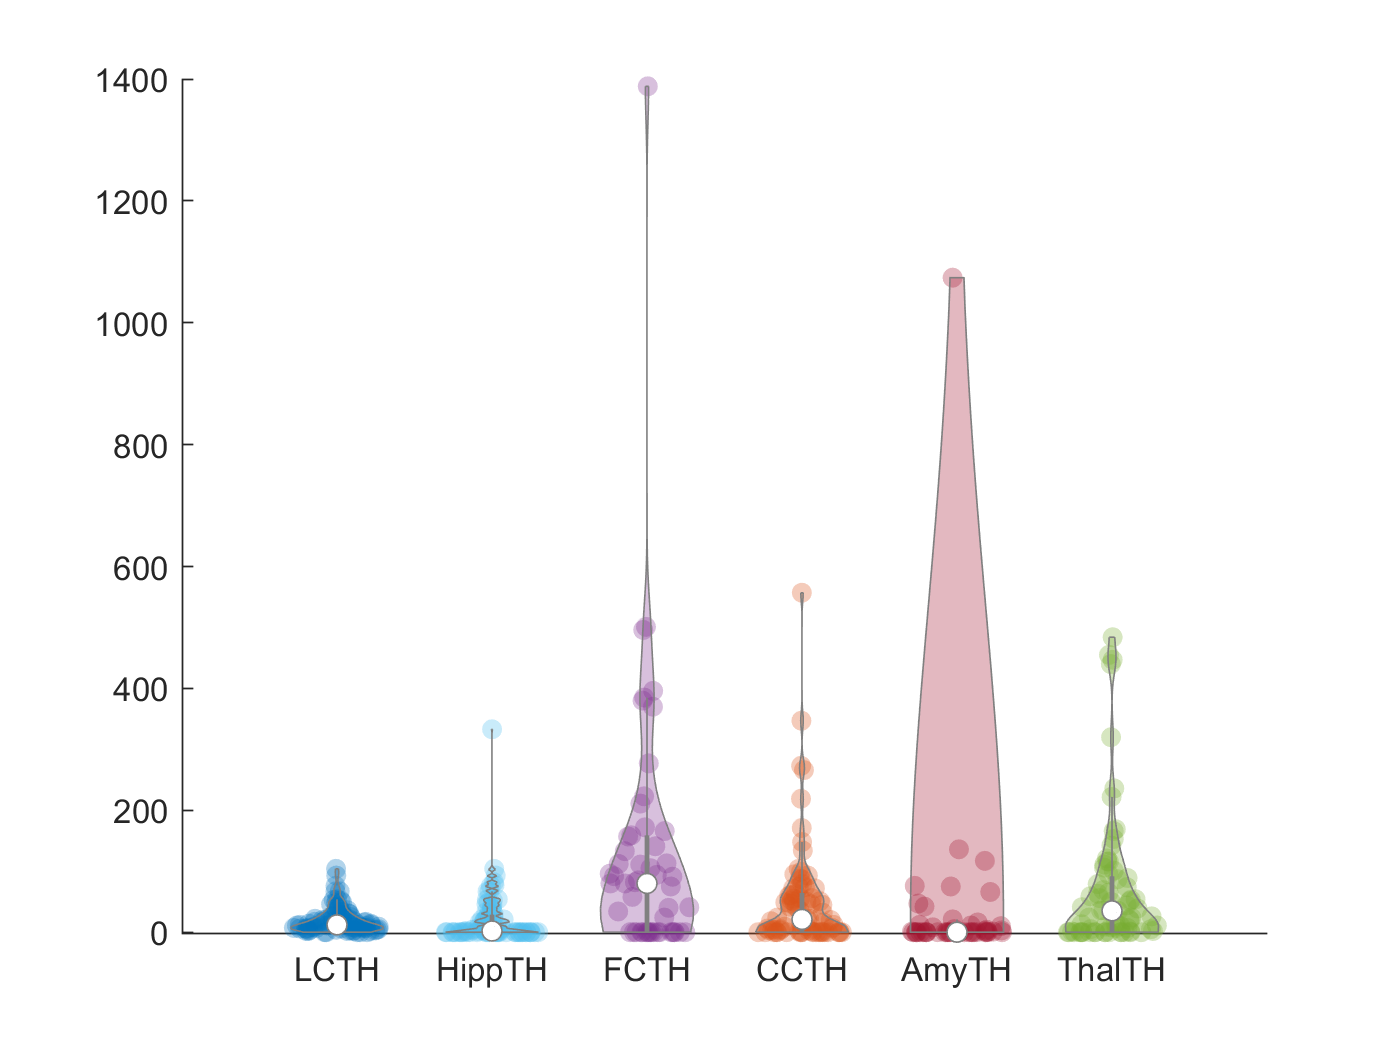


figure()
hold on
tmp=TABLE(:,2:7);   % get the 0-4th 
violins = violinplot(tmp);
hold off